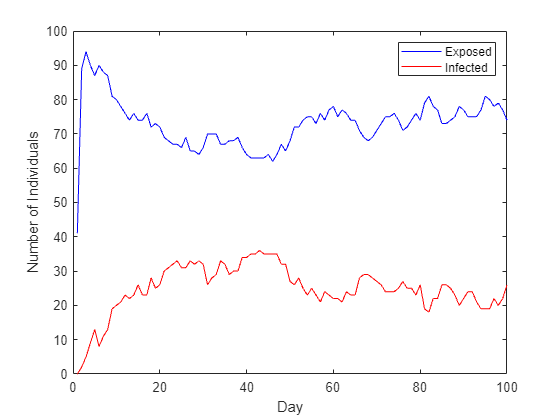

% Step 1. Set up Network Representation
% Number of individuals
N = 100;

% Random symmetric matrix
network = randi([0, 1], N);
network = triu(network, 1);
network = network + network';

% Initialize the state of individuals (0 = Susceptible, 1 = Infected)
state = zeros(N, 1);

% Randomly assign a few individuals as Infected
num_initially_infected = 5;
infected_indices = randperm(N, num_initially_infected);
state(infected_indices) = 1;

% Step 2. Simulate

% CUSTOMIZE PARAMETERS %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
num_days = 100;                                 % days
expose_prob = 0.05;                             % exposure prob
infect_prob = 0.04;                             % infection prob (4% was given in paper)
recover_prob = 0.1;                             % recovery prob
num_exposed = zeros(num_days, 1);               % Vector of exposed individuals each day
num_infected = zeros(num_days, 1);              % Vector of infected individuals each day
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for day = 1:num_days                            % For each day...
    for i = 1:N                                 % For each individual...
        if state(i) == 1                        % If they are infected...
            contacts = find(network(i, :));     % Find the individuals they are in contact with...
            for j = contacts                    % For each contact...
                if state(j) == 0                % If the contact is susceptible...
                    if rand < expose_prob       % They become exposed with expose_prob
                        state(j) = 1;          
                    end
                end
            end
            if rand < infect_prob               % The exposed individual becomes infected with infect_prob
                state(i) = 2;
            end
        elseif state(i) == 2                    % If the individual is infected...
            if rand < recover_prob              % The infected individual recovers with recover_prob
                state(i) = 0;
            end
        end
    end  
    % Record the number of exposed and infected individuals
    num_exposed(day) = sum(state == 1);
    num_infected(day) = sum(state == 2);
end

% Plot the number of exposed and infected individuals over time
figure;
plot(1:num_days, num_exposed, 'b');
hold on;
plot(1:num_days, num_infected, 'r');
xlabel('Day');
ylabel('Number of Individuals');
legend('Exposed', 'Infected');